# CNN for landscape distribution evaluation via remote sensing

## Set-up introduction

% Folder definition
mainFolder = 'C:/Users/mseld/Desktop/Desertification modelling/Data'; % Main data folder path

trainingImagesFolder = '/Training data'; % Sub-folder of 'mainFolder' containing training data
patchFolder = sprintf('%s/%s/Patches/', mainFolder, trainingImagesFolder); % Folder containing the patches
patchesPerImage = 1600;

checkpointFolder = 'C:/Users/mseld/Desktop/Desertification modelling/Models/Checkpoints';  % Folder for checkpoint saving
modelFolder = 'C:/Users/mseld/Desktop/Desertification modelling/Models';  % Folder for model saving
trainingOptionsFolder = 'C:/Users/mseld/Desktop/Desertification modelling/Models/Layers and options'; % Folder containing training layers and options
trainingFolder = 'C:/Users/mseld/Desktop/Desertification modelling/Results/Training'; % Folder containing the training metrics results

testFolder = '/Test data';
predictionsFolder = 'C:\Users\mseld\Desktop\Desertification modelling\Results\Predictions';
metricsFolder = 'C:\Users\mseld\Desktop\Desertification modelling\Results\Metrics';
graphsFolder = "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs"

graphsFolder = "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs"


% Getting date and time to recognize saved files
currentDateTime = datetime('now', 'Format', 'yyyy-MM-dd_HH-mm-ss');
dateTime = char(currentDateTime);  % Convert to character array

## Image processing

% Loads the files in the 'Raw images' folder
[numFiles, filePaths] = loadData(mainFolder, trainingImagesFolder)

% Preprocessing of the data loaded
for i = 1:numFiles
    preProcessing(mainFolder, trainingImagesFolder, filePaths, 'true', i) 
end

% Labelling of the patches
labelling(mainFolder, trainingImagesFolder) 

% Data augmentation (for training)
augmentPatches(patchFolder);

## Cosine annealing training

% Load the patch images using imageDatastore
imds = imageDatastore(patchFolder, 'FileExtensions', '.tif', 'LabelSource', 'none');

% Load the proportion labels
load('patch_proportions_table.mat', 'proportionTable');  % Load proportions for each patch
proportionLabels = table2array(proportionTable(:, {'Water', 'Vegetation', 'Desert'}));

% Shuffle the data and split into training and validation sets (85% train, 15% validation)
numPatches = numel(imds.Files);
indices = randperm(numPatches);
splitIdx = round(0.85 * numPatches);
trainIdx = indices(1:splitIdx);
valIdx = indices(splitIdx+1:end);

% Create training and validation datastores
imdsTrain = subset(imds, trainIdx);
imdsValidation = subset(imds, valIdx);
proportionLabelsTrain = proportionLabels(trainIdx, :);
proportionLabelsValidation = proportionLabels(valIdx, :);

trainDatastore = combine(imdsTrain, arrayDatastore(proportionLabelsTrain));
validationDatastore = combine(imdsValidation, arrayDatastore(proportionLabelsValidation));

% --- Define CNN Architecture ---
layers = [
    imageInputLayer([128 128 3])
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 256, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    fullyConnectedLayer(512)
    reluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(3)
    regressionLayer
];

% Define initial training parameters for cosine annealing
initialLR = 1e-4;        % Starting learning rate for warm-up
maxLR = 1e-3;            % Maximum learning rate after warm-up
minLR = 1e-5;            % Minimum learning rate (final rate in annealing phase)
warmUpEpochs = 3;        % Number of epochs for the warm-up phase
totalEpochs = 12;         % Total number of epochs
patience = 3;            % Early stopping patience (stop if no improvement after 1 epoch)

% Generate a custom learning rate schedule for cosine annealing with warm-up
learningRates = zeros(totalEpochs, 1);
for epoch = 1:totalEpochs
    learningRates(epoch) = cosineAnnealingWithWarmUp(epoch, initialLR, maxLR, minLR, warmUpEpochs, totalEpochs);
end

% --- Save the training options and learning rate schedule to a file ---
trainingOptionsFile = sprintf('%s/trainingOptions_%s.txt', trainingOptionsFolder, dateTime);

% Ensure the options directory exists
if ~exist(trainingOptionsFolder, 'dir')
    mkdir(trainingOptionsFolder);
end

% Ensure the checkpoint directory exists
if ~exist(checkpointFolder, 'dir')
    mkdir(checkpointFolder);
end

% Open the file for writing
fid = fopen(trainingOptionsFile, 'w');

% Write the training options to the file
fprintf(fid, 'Number of images processed: %d\n', numPatches);
fprintf(fid, 'MiniBatchSize: %d\n', 32);
fprintf(fid, 'MaxEpochs: %d\n', totalEpochs);
fprintf(fid, 'InitialLearnRate: %.4f\n', maxLR);
fprintf(fid, 'MaxLearningRate: %.4f\n', maxLR);
fprintf(fid, 'MinLearningRate: %.4f\n', minLR);
fprintf(fid, 'WarmUpEpochs: %d\n', warmUpEpochs);
fprintf(fid, 'L2Regularization: %.4f\n', 0.005);
fprintf(fid, 'ValidationFrequency: %d\n', 1700);
fprintf(fid, 'CheckpointPath: %s\n', checkpointFolder);

% Write the custom learning rate schedule for each epoch
fprintf(fid, '\nCustom Learning Rate Schedule:\n');
for epoch = 1:totalEpochs
    fprintf(fid, 'Epoch %d: Learning Rate = %.6f\n', epoch, learningRates(epoch));
end

% Close the file
fclose(fid);
disp('Training options and learning rate schedule saved as a text file.');

% Initialize early stopping and best validation RMSE tracker
bestValidationRMSE = inf;
epochsSinceImprovement = 0;

% Initialize arrays to store training info
trainingInfo.TrainingLoss = [];
trainingInfo.ValidationLoss = [];
trainingInfo.TrainingRMSE = [];
trainingInfo.ValidationRMSE = [];
trainingInfo.BaseLearnRate = [];

% --- Training loop with continuation across epochs and early stopping ---
for epoch = 1:totalEpochs
    % Set the current learning rate from the schedule
    currentLR = learningRates(epoch);

    % Define training options for the current epoch
    options = trainingOptions('sgdm', ...
        'MiniBatchSize', 32, ...
        'MaxEpochs', 1, ...  % Train one epoch at a time
        'InitialLearnRate', currentLR, ...
        'L2Regularization', 0.005, ...
        'ValidationData', validationDatastore, ...
        'ValidationFrequency', 1700, ...
        'CheckpointPath', checkpointFolder, ...  % Save checkpoints here
        'Verbose', true, ...
        'Plots', 'training-progress');

    % Train for one epoch and retrieve the updated layers
    [net, epochInfo] = trainNetwork(trainDatastore, layers, options);

    % Extract layers from trained network and reassign to 'layers' variable
    layers = net.Layers;

    % Append training metrics to trainingInfo
    trainingInfo.TrainingLoss = [trainingInfo.TrainingLoss; epochInfo.TrainingLoss];
    trainingInfo.ValidationLoss = [trainingInfo.ValidationLoss; epochInfo.ValidationLoss];
    trainingInfo.TrainingRMSE = [trainingInfo.TrainingRMSE; epochInfo.TrainingRMSE];
    trainingInfo.ValidationRMSE = [trainingInfo.ValidationRMSE; epochInfo.ValidationRMSE];
    trainingInfo.BaseLearnRate = [trainingInfo.BaseLearnRate; currentLR];

    % Save checkpoint manually after each epoch
    checkpointFile = sprintf('%s/checkpoint_epoch_%d.mat', checkpointFolder, epoch);
    save(checkpointFile, 'net', 'layers', 'options');
    disp(['Checkpoint saved at: ', checkpointFile]);

    % Early stopping logic
    currentValidationRMSE = epochInfo.ValidationRMSE(end);
    if currentValidationRMSE < bestValidationRMSE
        bestValidationRMSE = currentValidationRMSE;
        epochsSinceImprovement = 0;  % Reset patience counter
    else
        epochsSinceImprovement = epochsSinceImprovement + 1;
    end

    % Stop training if no improvement in the specified patience period
    if epochsSinceImprovement >= patience
        disp('Early stopping triggered.');
        break;
    end
end

% Ensure the model directory exists
if ~exist(modelFolder, 'dir')
    mkdir(modelFolder);
    disp('Model directory created.');
else
    disp('Model directory already exists.');
end

% Save final model and training information as before
modelFileName = sprintf('%s/trainedModel_%s.mat', modelFolder, dateTime);
save(modelFileName, 'net', 'layers', 'options');
disp(['Model saved at: ', modelFileName]);

% Flatten the arrays by concatenating them column-wise
totalIterations = numel(trainingInfo.TrainingLoss);  % Should be 12 * 1700 = 20400

% Create iteration counter
iterationCounter = (1:totalIterations)';

% Flatten each metric array
trainingLoss = reshape(trainingInfo.TrainingLoss', [], 1);
trainingRMSE = reshape(trainingInfo.TrainingRMSE', [], 1);
validationLoss = reshape(trainingInfo.ValidationLoss', [], 1);
validationRMSE = reshape(trainingInfo.ValidationRMSE', [], 1);

% Correctly expand learning rate for each iteration
baseLearnRate = repelem(trainingInfo.BaseLearnRate, 1700);  % Repeat each learning rate 1700 times to match iterations

% Create the flattened table as before
trainingTable = table(iterationCounter, trainingLoss, trainingRMSE, validationLoss, validationRMSE, baseLearnRate, ...
    'VariableNames', {'Iteration', 'TrainingLoss', 'TrainingRMSE', 'ValidationLoss', 'ValidationRMSE', 'LearningRate'});

% Extract validation points (once every 1700 iterations)
validationIterations = 1700 * (1:totalEpochs)';  % Indices where validation occurs
validationRMSEPoints = trainingTable.ValidationRMSE(validationIterations);
validationLossPoints = trainingTable.ValidationLoss(validationIterations);

% Save the flattened training metrics as a text file
trainingMetricsFile = sprintf('%s/trainingMetrics_flat_%s.txt', trainingFolder, dateTime);
writetable(trainingTable, trainingMetricsFile, 'Delimiter', '\t');
disp(['Flattened training metrics saved to: ', trainingMetricsFile]);

% Save the flattened training metrics as a MATLAB file
save('trainingMetrics_flat.mat', 'trainingTable');
disp('Flattened training metrics saved as a MATLAB table in trainingMetrics_flat.mat');

% Plot the Training and Validation metrics from the flattened table
figure;

% Plot Training and Validation RMSE
subplot(2, 1, 1);
plot(trainingTable.Iteration, trainingTable.TrainingRMSE, 'b-', 'LineWidth', 0.1);
hold on;
plot(validationIterations, validationRMSEPoints, 'r--o', 'LineWidth', 1.5, 'MarkerIndices', 1:length(validationIterations));
legend('Training RMSE', 'Validation RMSE');
xlabel('Iteration');
ylabel('RMSE');
title('Training and Validation RMSE');
grid on;
ylim([0 0.2]); % Adjust Y-axis range based on observed values

% Plot Training and Validation Loss
subplot(2, 1, 2);
plot(trainingTable.Iteration, trainingTable.TrainingLoss, 'b-', 'LineWidth', 0.1);
hold on;
plot(validationIterations, validationLossPoints, 'r--o', 'LineWidth', 1.5, 'MarkerIndices', 1:length(validationIterations));
legend('Training Loss', 'Validation Loss');
xlabel('Iteration');
ylabel('Loss');
title('Training and Validation Loss');
grid on;
ylim([0 0.06]); % Adjust Y-axis range based on observed values

% Save the plot to a file
trainingPlotFile = sprintf('%s/trainingProgress_%s.png', trainingFolder, dateTime);
saveas(gcf, trainingPlotFile);
disp(['Training plot saved to: ', trainingPlotFile]);

## Testing

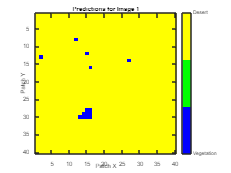

    "Prediction grid for image "    "1"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_1.png"



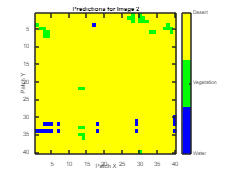

    "Prediction grid for image "    "2"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_2.png"



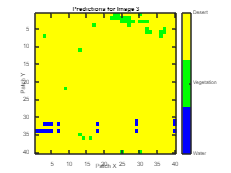

    "Prediction grid for image "    "3"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_3.png"



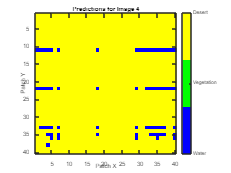

    "Prediction grid for image "    "4"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_4.png"



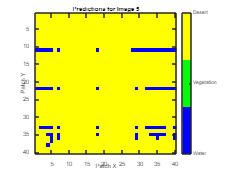

    "Prediction grid for image "    "5"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_5.png"



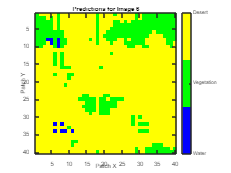

    "Prediction grid for image "    "6"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_6.png"



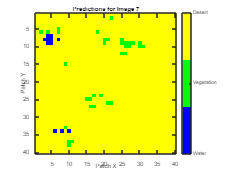

    "Prediction grid for image "    "7"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_7.png"



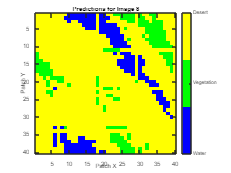

    "Prediction grid for image "    "8"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_8.png"



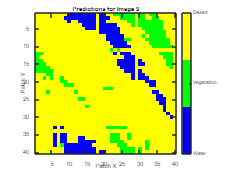

    "Prediction grid for image "    "9"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_9.png"



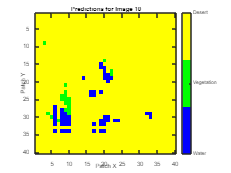

    "Prediction grid for image "    "10"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_10.png"



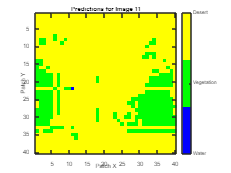

    "Prediction grid for image "    "11"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_11.png"



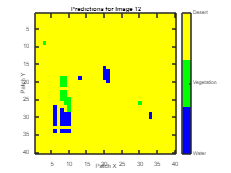

    "Prediction grid for image "    "12"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_12.png"



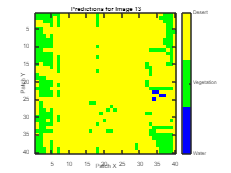

    "Prediction grid for image "    "13"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_13.png"



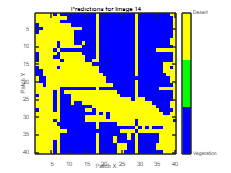

    "Prediction grid for image "    "14"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_14.png"



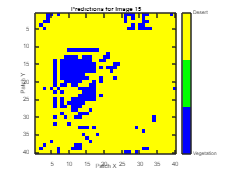

    "Prediction grid for image "    "15"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_15.png"



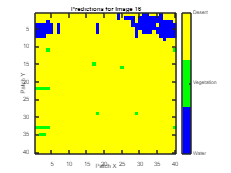

    "Prediction grid for image "    "16"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_16.png"



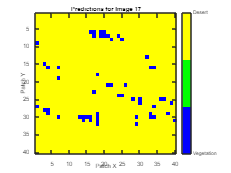

    "Prediction grid for image "    "17"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_17.png"



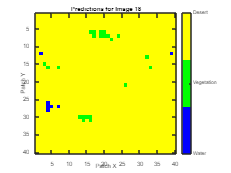

    "Prediction grid for image "    "18"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_18.png"



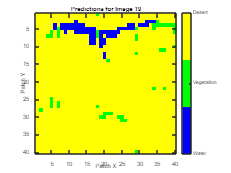

    "Prediction grid for image "    "19"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_19.png"



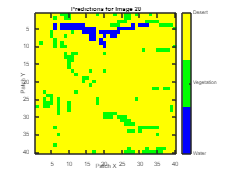

    "Prediction grid for image "    "20"    " saved at: "    "C:\Users\mseld\Desktop\Desertification modelling\Results\Graphs\prediction_grid_image_20.png"



% Select the model you want to use
modelFile = 'C:\Users\mseld\Desktop\Desertification modelling\Models\model_BRG±5%_SAT±5%.mat';

% Load the single model 'net' into the workspace
load(modelFile, 'net');
modelName = 'model_BRG±5%_SAT±5%';

disp(['Model loaded: ', modelName]);  % Display the loaded model name

[numFiles, filePaths] = loadData(mainFolder, testFolder) % Load files in 'Raw images' folder

for i = 1:numFiles
    preProcessing(mainFolder, testFolder, filePaths, 'false', i); % Preprocess loaded data
end

testLabelling(mainFolder, testFolder); % Label patches

% Load the test patches into an imageDatastore
patchFolder = sprintf('%s/%s/Patches/', mainFolder, testFolder);
imdsTest = imageDatastore(patchFolder, 'FileExtensions', '.tif', 'LabelSource', 'none');

% Load the test labels (proportion labels for each patch)
load('test_patch_proportions_table.mat', 'testProportionTable');  % Ground truth labels

% Convert the table to an array for evaluation
proportionLabelsTest = table2array(testProportionTable(:, {'Water', 'Vegetation', 'Desert'}));

% Make predictions using the single model
YPred = predict(net, imdsTest);

% Ensure predictions are non-negative and normalize proportions to sum to 1
YPred(YPred < 0) = 0;  
YPredNormalized = YPred ./ sum(YPred, 2);

% Ensure YPredNormalized has the correct size
if size(YPredNormalized, 1) ~= length(filePaths) * patchesPerImage
    error('Mismatch between the number of patches and images. Each image should correspond to exactly 1600 patches.');
end

% Calculate the total number of images
numImages = size(YPredNormalized, 1) / patchesPerImage;

% Initialize arrays for averaged proportions and image names
avgWaterPerImage = zeros(numImages, 1);
avgVegetationPerImage = zeros(numImages, 1);
avgDesertPerImage = zeros(numImages, 1);
imageNames = cell(numImages, 1);

% Process each image to calculate and store averaged proportions
for i = 1:numImages
    patchStart = (i - 1) * patchesPerImage + 1;
    patchEnd = i * patchesPerImage;

    patchesForImage = YPredNormalized(patchStart:patchEnd, :);

    % Check number of rows for each image
    assert(size(patchesForImage, 1) == patchesPerImage, 'Incorrect number of patches for image %d', i);

    % Compute sum of proportions for Water, Vegetation, and Desert
    sumWaterPerImage = sum(patchesForImage(:, 1));
    sumVegetationPerImage = sum(patchesForImage(:, 2));
    sumDesertPerImage = sum(patchesForImage(:, 3));

    % Renormalize and round proportions
    totalSum = sumWaterPerImage + sumVegetationPerImage + sumDesertPerImage;
    waterProp = sumWaterPerImage / totalSum;
    vegetationProp = sumVegetationPerImage / totalSum;
    desertProp = sumDesertPerImage / totalSum;

    % Round values to 4 decimal places
    waterPropRounded = round(waterProp, 4);
    vegetationPropRounded = round(vegetationProp, 4);
    desertPropRounded = round(desertProp, 4);

    % Adjust to ensure sum of 1 if needed
    roundedTotal = waterPropRounded + vegetationPropRounded + desertPropRounded;
    if roundedTotal ~= 1
        [~, idxMax] = max([waterPropRounded, vegetationPropRounded, desertPropRounded]);
        switch idxMax
            case 1
                waterPropRounded = waterPropRounded + (1 - roundedTotal);
            case 2
                vegetationPropRounded = vegetationPropRounded + (1 - roundedTotal);
            case 3
                desertPropRounded = desertPropRounded + (1 - roundedTotal);
        end
    end

    % Store adjusted proportions
    avgWaterPerImage(i) = waterPropRounded;
    avgVegetationPerImage(i) = vegetationPropRounded;
    avgDesertPerImage(i) = desertPropRounded;

    [~, imageName, ext] = fileparts(filePaths{i});
    imageNames{i} = [imageName, ext];

    disp(['Processing image: ', imageNames{i}, ', with patches from ', num2str(patchStart), ' to ', num2str(patchEnd)]);
end

% Create a table for results
imageAveragedPredictions = table(imageNames, avgWaterPerImage, avgVegetationPerImage, avgDesertPerImage, ...
    'VariableNames', {'ImageName', 'WaterProportion', 'VegetationProportion', 'DesertProportion'});

% Display and save results
disp(imageAveragedPredictions);

matFileName = sprintf('%s/imageAveragedPrediction_%s_%s.mat', predictionsFolder, modelName, dateTime);
csvFileName = sprintf('%s/imageAveragedPredictions_%s_%s.csv', predictionsFolder, modelName, dateTime);

save(matFileName, 'imageAveragedPredictions');
writetable(imageAveragedPredictions, csvFileName);

disp(['Predictions saved as .mat file at: ', matFileName]);
disp(['Predictions saved as .csv file at: ', csvFileName]);

% Calculate RMSE
rmseWater = sqrt(mean((YPredNormalized(:, 1) - proportionLabelsTest(:, 1)).^2));
rmseVegetation = sqrt(mean((YPredNormalized(:, 2) - proportionLabelsTest(:, 2)).^2));
rmseDesert = sqrt(mean((YPredNormalized(:, 3) - proportionLabelsTest(:, 3)).^2));

% Calculate R-squared for each class
ssResWater = sum((YPredNormalized(:, 1) - proportionLabelsTest(:, 1)).^2);
ssTotWater = sum((proportionLabelsTest(:, 1) - mean(proportionLabelsTest(:, 1))).^2);
rSquaredWater = 1 - (ssResWater / ssTotWater);

ssResVegetation = sum((YPredNormalized(:, 2) - proportionLabelsTest(:, 2)).^2);
ssTotVegetation = sum((proportionLabelsTest(:, 2) - mean(proportionLabelsTest(:, 2))).^2);
rSquaredVegetation = 1 - (ssResVegetation / ssTotVegetation);

ssResDesert = sum((YPredNormalized(:, 3) - proportionLabelsTest(:, 3)).^2);
ssTotDesert = sum((proportionLabelsTest(:, 3) - mean(proportionLabelsTest(:, 3))).^2);
rSquaredDesert = 1 - (ssResDesert / ssTotDesert);

% Print R-squared on screen
disp('RMSE Values:');
disp(['RMSE for Water: ', num2str(rmseWater)]);
disp(['RMSE for Vegetation: ', num2str(rmseVegetation)]);
disp(['RMSE for Desert: ', num2str(rmseDesert)]);
disp('R-Squared Values:');
disp(['R-Squared for Water: ', num2str(rSquaredWater)]);
disp(['R-Squared for Vegetation: ', num2str(rSquaredVegetation)]);
disp(['R-Squared for Desert: ', num2str(rSquaredDesert)]);

% Save the RMSE and R-squared results to a text file
metricsResultsFile = sprintf('%s/metricsResults_%s_%s.txt', metricsFolder, modelName, dateTime);
fid = fopen(metricsResultsFile, 'w');

% Write the metrics information to the file
% fprintf(fid, 'Final Validation RMSE: %.4f\n', trainingInfo.FinalValidationRMSE);
% fprintf(fid, 'Final Validation Loss: %.4f\n', trainingInfo.FinalValidationLoss);
% fprintf(fid, 'Final Training Iterations: %d\n', trainingInfo.OutputNetworkIteration);
fprintf(fid, 'Model used:%s\n', modelName);
fprintf(fid, '\nRMSE for Water: %.4f\n', rmseWater);
fprintf(fid, 'RMSE for Vegetation: %.4f\n', rmseVegetation);
fprintf(fid, 'RMSE for Desert: %.4f\n', rmseDesert);
fprintf(fid, '\nR-Squared for Water: %.4f\n', rSquaredWater);
fprintf(fid, 'R-Squared for Vegetation: %.4f\n', rSquaredVegetation);
fprintf(fid, 'R-Squared for Desert: %.4f\n', rSquaredDesert);
fclose(fid);
disp(['Metrics results saved at: ', metricsResultsFile]);

% Print the predicted proportions and save them to a text file
predictedResultsFileTxt = sprintf('%s/predicted_proportions_%s_%s.txt', predictionsFolder, modelName, dateTime);
fid = fopen(predictedResultsFileTxt, 'w');
fprintf(fid, 'Model used:%s\n\n', modelName);
fprintf(fid, 'Predicted Proportions for Test Patches:\n');
fprintf(fid, 'Patch\tWater\tVegetation\tDesert\n');
disp('Predicted Proportions:');

for i = 1:size(YPredNormalized, 1)
    fprintf(fid, '%d\t%.4f\t%.4f\t%.4f\n', i, YPredNormalized(i, 1), YPredNormalized(i, 2), YPredNormalized(i, 3));
    % disp(['Patch ', num2str(i), ': Water = ', num2str(YPredNormalized(i, 1)), ...
    %      ', Vegetation = ', num2str(YPredNormalized(i, 2)), ...
    %      ', Desert = ', num2str(YPredNormalized(i, 3))]);
end

fclose(fid);
disp(['Predicted proportions saved as text file at: ', predictedResultsFileTxt]);

% Save the predicted results to a .mat file for future analysis
predictedResultsFile = sprintf('%s/predicted_proportions_%s_%s.mat', predictionsFolder, modelName, dateTime);
save(predictedResultsFile, 'YPredNormalized');
disp(['Predicted proportions saved at: ', predictedResultsFile]);

% Sum the predictions across all patches to get a final estimate for the complete image
totalWater = sum(YPredNormalized(:, 1));      % Sum of all predicted 'Water' proportions
totalVegetation = sum(YPredNormalized(:, 2)); % Sum of all predicted 'Vegetation' proportions
totalDesert = sum(YPredNormalized(:, 3));     % Sum of all predicted 'Desert' proportions

% Normalize the total predictions to get proportions for the complete image
totalSum = totalWater + totalVegetation + totalDesert;  % Total sum of the summed predictions
finalWaterProportion = totalWater / totalSum;           % Final 'Water' proportion for the full image
finalVegetationProportion = totalVegetation / totalSum; % Final 'Vegetation' proportion for the full image
finalDesertProportion = totalDesert / totalSum;         % Final 'Desert' proportion for the full image

% Sum the actual labeled proportions to get the ground truth for the complete image
actualWater = sum(proportionLabelsTest(:, 1));      % Sum of actual 'Water' proportions from labels
actualVegetation = sum(proportionLabelsTest(:, 2)); % Sum of actual 'Vegetation' proportions from labels
actualDesert = sum(proportionLabelsTest(:, 3));     % Sum of actual 'Desert' proportions from labels

% Normalize the actual labeled proportions
actualTotalSum = actualWater + actualVegetation + actualDesert;
finalActualWaterProportion = actualWater / actualTotalSum;
finalActualVegetationProportion = actualVegetation / actualTotalSum;
finalActualDesertProportion = actualDesert / actualTotalSum;

% Display the final proportions for the complete image
disp('Final Proportions for the Complete Image (Predicted vs Actual):');
disp(['Water (Predicted): ', num2str(finalWaterProportion), ', Water (Actual): ', num2str(finalActualWaterProportion)]);
disp(['Vegetation (Predicted): ', num2str(finalVegetationProportion), ', Vegetation (Actual): ', num2str(finalActualVegetationProportion)]);
disp(['Desert (Predicted): ', num2str(finalDesertProportion), ', Desert (Actual): ', num2str(finalActualDesertProportion)]);

% Save the final proportions to a text file
finalResultsFile = sprintf('%s/final_proportions_%s_%s.txt', predictionsFolder, modelName, dateTime);
fid = fopen(finalResultsFile, 'w');
fprintf(fid, 'Model used:%s\n\n', modelName);
fprintf(fid, 'Final Proportions for the Complete Image (Predicted vs Actual):\n');
fprintf(fid, 'Water (Predicted): %.4f, Water (Actual): %.4f\n', finalWaterProportion, finalActualWaterProportion);
fprintf(fid, 'Vegetation (Predicted): %.4f, Vegetation (Actual): %.4f\n', finalVegetationProportion, finalActualVegetationProportion);
fprintf(fid, 'Desert (Predicted): %.4f, Desert (Actual): %.4f\n', finalDesertProportion, finalActualDesertProportion);
fclose(fid);
disp(['Final proportions saved at: ', finalResultsFile]);

% Save the final proportions to a .mat file for future use
finalResultsMatFile = sprintf('%s/final_proportions_%s_%s.mat', predictionsFolder, modelName, dateTime);
save(finalResultsMatFile, 'finalWaterProportion', 'finalVegetationProportion', 'finalDesertProportion', ...
     'finalActualWaterProportion', 'finalActualVegetationProportion', 'finalActualDesertProportion');
disp(['Final proportions saved at: ', finalResultsMatFile]);

% Create a bar chart comparing predicted and actual proportions
figure;
xLabels = {'Water', 'Vegetation', 'Desert'};  % X-axis labels
predictedProportions = [finalWaterProportion, finalVegetationProportion, finalDesertProportion];
actualProportions = [finalActualWaterProportion, finalActualVegetationProportion, finalActualDesertProportion];

% Create a bar chart with two bars for each category (predicted and actual)
barData = [predictedProportions; actualProportions]';
b = bar(barData);
b(1).FaceColor = 'g';  % Predicted bar color
b(2).FaceColor = 'b';  % Actual bar color
legend({'Predicted', 'Actual'}, 'Location', 'northeastoutside');
set(gca, 'XTickLabel', xLabels);
xlabel('Classes');
ylabel('Proportion');
title('Predicted vs Actual Proportions for the Complete Image');
grid on;

% Save the bar chart as an image
histogramFile = sprintf('%s/proportion_comparison_histogram_%s_%s.png', graphsFolder, modelName, dateTime);
saveas(gcf, histogramFile);
disp(['Comparison histogram saved at: ', histogramFile]);

% Visualize results (scatter plots) and save them as images
figure;
subplot(2, 2, 1);
scatter(proportionLabelsTest(:, 1), YPredNormalized(:, 1));
xlabel('Actual Water Proportion');
ylabel('Predicted Water Proportion');
title('Water');
hold on;
% Add the y = x line
xLimits = xlim;
yLimits = ylim;
minLimit = max([xLimits(1), yLimits(1)]);
maxLimit = min([xLimits(2), yLimits(2)]);
plot([minLimit, maxLimit], [minLimit, maxLimit], '--k');
hold off;

subplot(2, 2, 2);
scatter(proportionLabelsTest(:, 2), YPredNormalized(:, 2));
xlabel('Actual Vegetation Proportion');
ylabel('Predicted Vegetation Proportion');
title('Vegetation');
hold on;
% Add the y = x line
xLimits = xlim;
yLimits = ylim;
minLimit = max([xLimits(1), yLimits(1)]);
maxLimit = min([xLimits(2), yLimits(2)]);
plot([minLimit, maxLimit], [minLimit, maxLimit], '--k');
hold off;

subplot(2, 2, 3);
scatter(proportionLabelsTest(:, 3), YPredNormalized(:, 3));
xlabel('Actual Desert Proportion');
ylabel('Predicted Desert Proportion');
title('Desert');
hold on;
% Add the y = x line
xLimits = xlim;
yLimits = ylim;
minLimit = max([xLimits(1), yLimits(1)]);
maxLimit = min([xLimits(2), yLimits(2)]);
plot([minLimit, maxLimit], [minLimit, maxLimit], '--k');
hold off;

saveas(gcf, sprintf('%s/scatter_plots_%s_%s.png', graphsFolder, modelName, dateTime));  % Save figure

% Generate residuals for each class
residualsWater = proportionLabelsTest(:, 1) - YPredNormalized(:, 1);
residualsVegetation = proportionLabelsTest(:, 2) - YPredNormalized(:, 2);
residualsDesert = proportionLabelsTest(:, 3) - YPredNormalized(:, 3);

% Residuals Plot
figure;
subplot(1, 3, 1);
scatter(proportionLabelsTest(:, 1), residualsWater);
xlabel('Actual Water Proportion');
ylabel('Residuals');
title('Water Residuals');
yline(0, '--k'); % Add horizontal reference line at y = 0

subplot(1, 3, 2);
scatter(proportionLabelsTest(:, 2), residualsVegetation);
xlabel('Actual Vegetation Proportion');
ylabel('Residuals');
title('Vegetation Residuals');
yline(0, '--k'); % Add horizontal reference line at y = 0

subplot(1, 3, 3);
scatter(proportionLabelsTest(:, 3), residualsDesert);
xlabel('Actual Desert Proportion');
ylabel('Residuals');
title('Desert Residuals');
yline(0, '--k'); % Add horizontal reference line at y = 0

% Save the residuals plot as an image
residualsPlotFile = sprintf('%s/residuals_plot_%s_%s.png', graphsFolder, modelName, dateTime);
saveas(gcf, residualsPlotFile);
disp(['Residuals plot saved at: ', residualsPlotFile]);

% Histogram of Residuals
figure;
subplot(1, 3, 1);
histogram(residualsWater);
xlabel('Residuals');
ylabel('Frequency');
title('Water Residuals');
grid on;

subplot(1, 3, 2);
histogram(residualsVegetation);
xlabel('Residuals');
ylabel('Frequency');
title('Vegetation Residuals');
grid on;

subplot(1, 3, 3);
histogram(residualsDesert);
xlabel('Residuals');
ylabel('Frequency');
title('Desert Residuals');
grid on;

% Save the histogram of residuals as an image
residualsHistFile = sprintf('%s/residuals_histogram_%s_%s.png', graphsFolder, modelName, dateTime);
saveas(gcf, residualsHistFile);
disp(['Residuals histogram saved at: ', residualsHistFile]);

% Visualize the predictions for each image (40x40 grid)

% Determine the main class (Water, Vegetation, or Desert) for each patch
% Water is mapped to 1 (blue), Vegetation to 2 (green), Desert to 3 (yellow)
[~, maxClass] = max(YPredNormalized, [], 2);  % Get the index of the highest proportion

% Reshape the maxClass (patch classifications) into a 40x40 grid
gridSize = 40;
numImages = size(YPredNormalized, 1) / (gridSize * gridSize);
for imgIdx = 1:numImages
    % Extract the patches for the current image
    patchStart = (imgIdx - 1) * gridSize * gridSize + 1;
    patchEnd = imgIdx * gridSize * gridSize;
    patchesForImage = maxClass(patchStart:patchEnd);

    % Reshape the patches into a 40x40 grid
    predictionGrid = reshape(patchesForImage, gridSize, gridSize);

    % Rotate the grid 90 degrees clockwise to correct orientation
    predictionGrid = rot90(predictionGrid, -1);

    % Create a figure for the grid visualization
    figure;

    % Define the color map: Water (blue), Vegetation (green), Desert (yellow)
    colormap([0 0 1;  % Blue for Water
              0 1 0;  % Green for Vegetation
              1 1 0]); % Yellow for Desert

    % Display the grid using imagesc
    imagesc(predictionGrid);

    % Set the axes to be square
    axis equal;
    axis tight;

    % Add a title and labels
    title(sprintf('Predictions for Image %d', imgIdx));
    xlabel('Patch X');
    ylabel('Patch Y');

    % Add a colorbar for reference
    colorbar('Ticks', [1, 2, 3], 'TickLabels', {'Water', 'Vegetation', 'Desert'});

    % Save the figure as an image
    fileName = sprintf('prediction_grid_image_%d.png', imgIdx);
    visualizedPredictionsFolder = 'C:\Users\mseld\Desktop\Desertification modelling\Results\Predictions\Visualized predictions';
    saveas(gcf, fullfile(visualizedPredictionsFolder, fileName));

    % Display a message confirming the save
    disp(['Prediction grid for image ', num2str(imgIdx), ' saved at: ', fullfile(graphsFolder, fileName)]);
end